## 1. Write a function that calculates the correlation between two input vectors. Use only basic MATLAB functions (mean, std, ...).

% the size of vectors
size = 10;
% generate two random vectors with normal distribution
vector1 = randn(size, 1);
vector2 = randn(size, 1);
result = calculateCorr(vector1, vector2);
disp('Vector 1:');

Vector 1:


disp(transpose(vector1));

    0.5579   -0.7302    0.0696   -0.7094   -0.4146    1.0708    0.6674   -0.1046   -0.5123   -0.4172



disp('Vector 2:');

Vector 2:


disp(transpose(vector2));

    1.1614   -1.4037   -0.9828   -1.9036   -2.4896    0.0222    0.8156    2.1038   -1.2982    0.3042



disp('Correlation: ');

Correlation: 


disp(result);

    0.5619



## 2. Conduct Monte Carlo simulations in which samples are drawn from а Gaussian distribution with mean 10 and standard deviation 2. For each of various sample sizes (n = 2, 5, 10, 20, 50,100,200,500, 1000), draw 1,000 random samples, compute the mean of each sample, and quantify the spread in the results by computing standard deviation. Then make а line plot that shows the relationship between sample size (x-axis) and the uncertainty (spread) of the mean (y-axis). On the same figure, draw а line that shows the theoretical expectation.

inputMean = 10;
inputStndDvtn = 2;
samplesSizes = [2, 5, 10, 20, 50, 100, 200, 500, 1000];
samplesCount = 1000;
means = zeros(samplesCount, 1);
actualDevs = zeros(length(samplesSizes), 1);
theorDevs = zeros(length(samplesSizes), 1);

for i = 1 : length(samplesSizes)
    % generates samples 1000 times
    for j = 1 : samplesCount
        % generates a vector of n numbers with a mean 10 
        % and a standard deviation 2
        sample = inputStndDvtn * randn(samplesSizes(i), 1) + inputMean;
        % calculates the mean for each of the 1000 samples and save
        means(j) = mean(sample);
    end
    % calculate actual and theoretical standard deviations
    actualDevs(i) = std(means);
    theorDevs(i) = 2 / sqrt(samplesSizes(i));
end

%print actual and theoretical deviations values
disp('Actual standard deviations:');

Actual standard deviations:


disp(actualDevs.');

    1.4533    0.8968    0.6249    0.4432    0.2787    0.2001    0.1418    0.0914    0.0621



disp('Therotetical standard deviations:');

Therotetical standard deviations:


disp(theorDevs.');

    1.4142    0.8944    0.6325    0.4472    0.2828    0.2000    0.1414    0.0894    0.0632



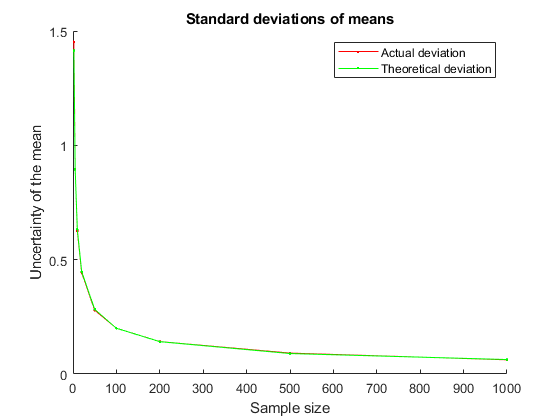


% draw a plot with 2 figures
figure;
hold on;

%r/g.- means 'r - red/ g - green, . - point markers, - solid line'
f1 = plot(samplesSizes, actualDevs, 'r.-');
f2 = plot(samplesSizes, theorDevs, 'g.-');
xlabel('Sample size');
ylabel('Uncertainty of the mean');
title('Standard deviations of means');
% legends
legend([f1 f2], {'Actual deviation', 'Theoretical deviation'});

## 3. Write а function that accepts an input vector and returns а new vector representing а bootstrap sample drawn from the original vector.

vectorSize = 10;
bootstrapVectorIn = randn(vectorSize, 1);
bootstrapVectorOut = getBootstrapVector(bootstrapVectorIn);
disp('Original vector:');

Original vector:


disp(bootstrapVectorIn');

    0.8760   -0.9005   -0.7185    0.8289    1.0727   -1.3697    0.7120   -0.7539    0.3806   -0.9062



disp('Bootstrapped vector:');

Bootstrapped vector:


disp(bootstrapVectorOut');

    1.0727    0.8760    1.0727    1.0727   -1.3697    1.0727   -0.9005    1.0727   -0.9005    0.8760



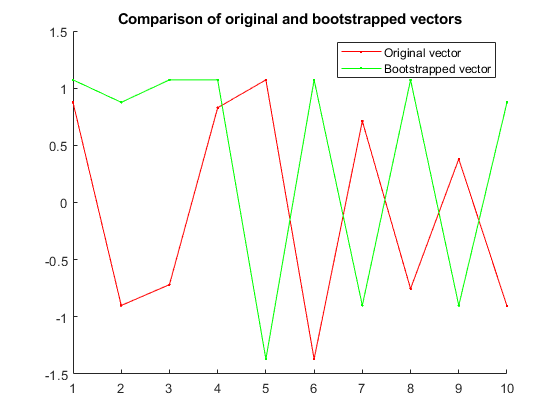


% visualize difference between input and bootstrapped vectors
figure; 
hold on;
v1 = plot(1:vectorSize, bootstrapVectorIn, 'r.-');
v2 = plot(1:vectorSize, bootstrapVectorOut, 'g.-');

title('Comparison of original and bootstrapped vectors');
legend([v1 v2], {'Original vector', 'Bootstrapped vector'});

## 4. Modify the function in Exercise 3 to accept another input specifying the number of bootstrap samples to draw. Then have the function return а 2D matrix with different bootstrap samples in the columns of the matrix. Avoid the use of for-loops in this function so that the function is fast.

vectorSizeNew = 5;
samplesCountNew = 2;

matrix2D = get2Dmatrix(vectorSizeNew, samplesCountNew);

Random vector of size 5:
   -0.9126    1.2971   -0.2152    0.7904    0.4127

Matrix of 2 bootstrapped vectors with length 5 (column = vector):
    1.2971   -0.2152
    0.4127    0.7904
    0.7904   -0.2152
   -0.9126    0.7904
   -0.2152   -0.9126



## 5. Generate some correlated data (two variables). Visualize the data using а scatter plot. Then compute а 2D histogram of these data and visualize the histogram as an image. Compute the marginal distribution of the data (showing the distribution of the data on each variable separately) and then compute the joint distribution that we would expect to observe if the variabes were independent. Visualize this distribution as an image.

% generate correlated data (two correlated vectors)
% use input values from Exercise 2:
% -- inputMean = 10;
% -- inputStndDvtn = 2;
desiredCorr = 0.75;

% generate a random matrix 'corrData' with 2 columns, corresponding to 2 vectors
% random elemnets are drawn from a standard normal distribution (randn())
corrData = inputMean + inputStndDvtn * randn(1000, 2);
% define the desired correlation in matrix R (0.75)
% R is trivially symmetric and positive definite
R = [1 desiredCorr; desiredCorr 1];
% returns an upper triangular matrix L (such that L'*L = R)
L = chol(R);
% M is multiplied with L in order to set the desired correlation
corrData = corrData * L;
% corrX, corrY - correlated vectors
corrX = corrData(:, 1);
corrY = corrData(:, 2);
fprintf('correlation btwn corrX and corrY: %f', corr(corrX, corrY));

correlation btwn corrX and corrY: 0.764783

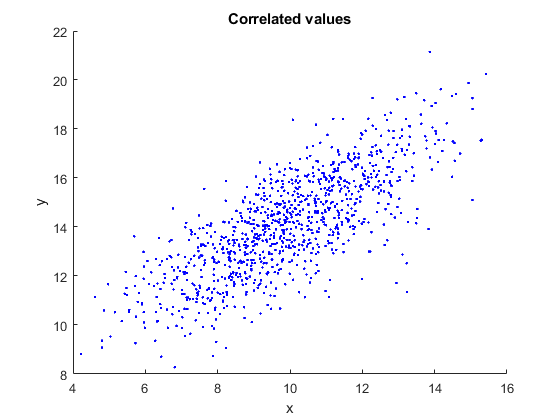

% visualize data using a scatter plot
figure;
scatter(corrX, corrY, 'b.');
xlabel('x');
ylabel('y');
title('Correlated values');

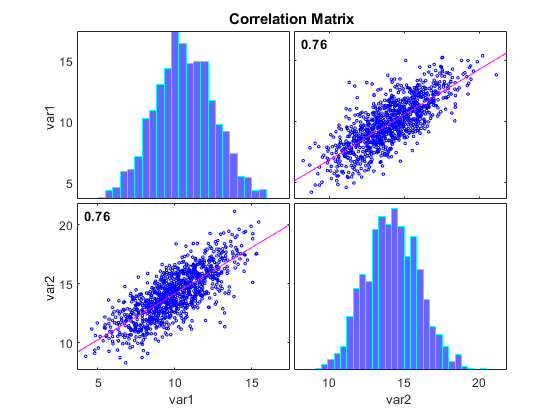

% visualize thr variable correlations
% along the diagonal - the histograms of the variables
% along the off diagonal - the scatter plots of variable pairs
figure;
corrplot(corrData);

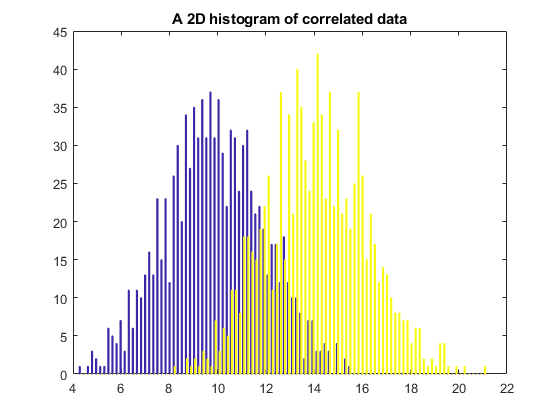

% a 2D histogram of generated data
figure;
hist(corrData, 100);
title('A 2D histogram of correlated data');

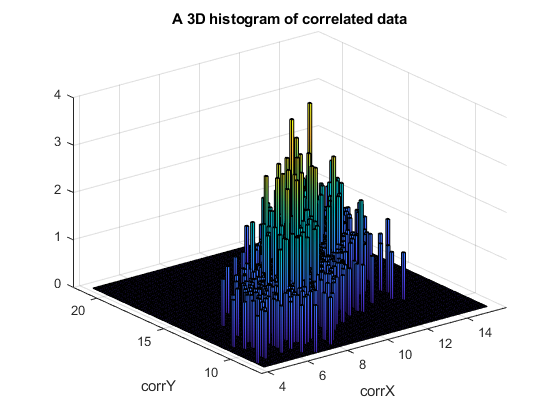

% a 3D histogram of generated data
% the height of each bar indicates the number of elements in bin
figure;
hist3(corrData, [100, 100], 'CDataMode', 'auto', 'FaceColor', 'interp');
xlabel('corrX');
ylabel('corrY');
title('A 3D histogram of correlated data');

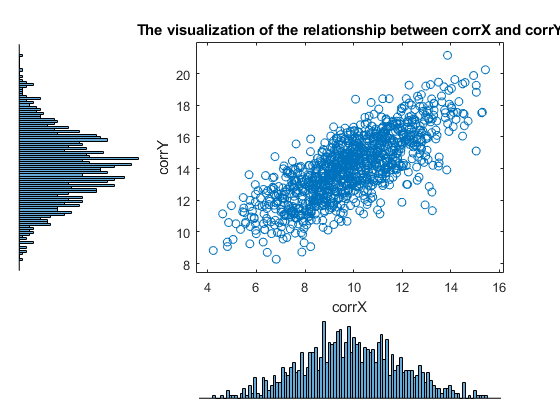

% 1. compute the marginal distribution of the data 
% for corrX and corrY variables separately -> 
% histograms on the horizontal and vertical axes of the scatter plot, respectively;
% 2. compute the joint distribution for corrX and corrY -> 
% the scatter plot;
figure;
scatterhist(corrX, corrY, 100);
xlabel('corrX');
ylabel('corrY');
title('The visualization of the relationship between corrX and corrY');

## ----------FUNCTIONS----------

% calculateCorr function
% ----
% calculates correlation between two input vectors 
% using 'corr()' Matlab method

function result = calculateCorr(vector1, vector2)
    result = corr(vector1, vector2);
end

% getBootstrapVector function
% ----
% gets a vector as an input
% returns a bootstrapped vector using random indices
function bootstrapVectorOut = getBootstrapVector(vector)
    indices = ceil(length(vector) * rand(length(vector), 1));
    
    bootstrapVectorOut = vector(indices);
end

% get2Dmatrix function
% ----
% gets a vector size and samples count as input
% generates a vector and calls the modified bootstrapping method
% returns a two-dimension matrix with bootstrapped vectors in columns
function matrix2D = get2Dmatrix(vectorSize, samplesCount)
    vector = randn(vectorSize, 1);
    fprintf('Random vector of size %d:\n', vectorSize);
    disp(vector');
    
    matrix2D = getBootstrapVectorModified(vector, samplesCount);
    fprintf('Matrix of %d bootstrapped vectors with length %d (column = vector):\n', samplesCount, vectorSize);
    disp(matrix2D);
end

% getBootstrapVectorModified function
% ----
% gets a vector and samples count as input
% returns a bootstrapped vector using random indices
function bootstrapMatrixOut = getBootstrapVectorModified(vector, samplesCount)
    indices = ceil(length(vector) * rand(length(vector), samplesCount));
    
    bootstrapMatrixOut = vector(indices);
end